# Exercise 3

clc;
close all;
clear variables;

set(groot, 'defaulttextinterpreter', 'latex');  
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');  
set(groot, 'defaultLegendInterpreter', 'latex');

## Task 1

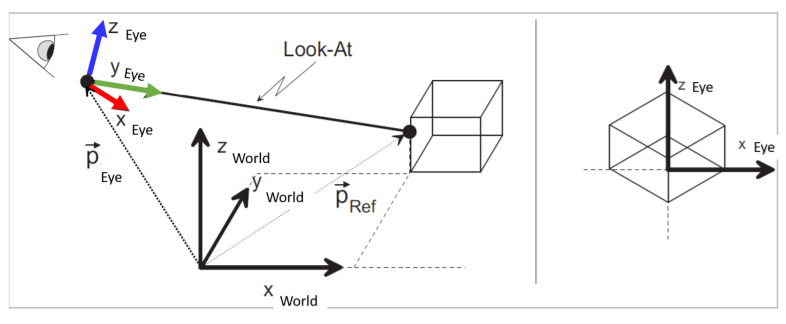

p_ref = sym('p_ref', [3 1])

$$p\_ref = \left(\begin{array}{c} p_{\mathrm{ref1}}\\ p_{\mathrm{ref2}}\\ p_{\mathrm{ref3}} \end{array}\right)$$

p_eye = sym('p_eye', [3 1])

$$p\_eye = \left(\begin{array}{c} p_{\mathrm{eye1}}\\ p_{\mathrm{eye2}}\\ p_{\mathrm{eye3}} \end{array}\right)$$

y_eye = (p_ref - p_eye) / norm(p_ref - p_eye);

z_world = sym('z_world', [3 1]);
x_eye = cross(y_eye, z_world) / norm(cross(y_eye, z_world));

z_eye = cross(x_eye, y_eye);

R = [x_eye, y_eye, z_eye]; % not 100 % sure on this one
T = [R, p_eye;
     0,0,0,1];

## Task 2

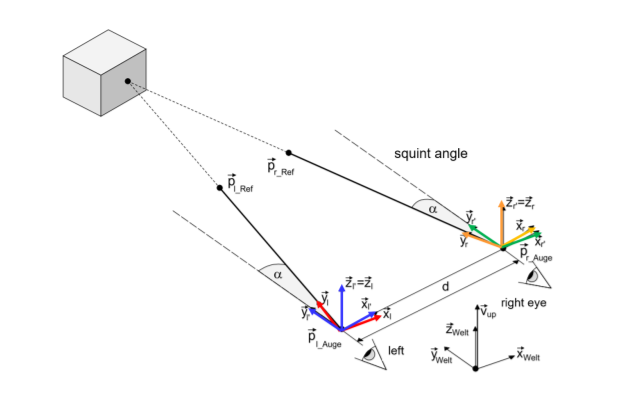

Rz = @(alpha) [cos(alpha), -sin(alpha), 0;
               sin(alpha),  cos(alpha), 0;
               0, 0, 1];
T_hom = @(R, p) [R, p;
                 0, 0, 0, 1];

Rotate about $z$ by $\alpha$

syms alpha d
T1 = T_hom(Rz(alpha), zeros(3, 1))

$$T1 = \left(\begin{array}{cccc} \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & 0\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Translate by $d$ over the $x$ axis

T2 = T_hom(eye(3), [d; 0; 0])

$$T2 = \left(\begin{array}{cccc} 1 & 0 & 0 & d\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Rotate about $z$ by $\alpha$

T3 = T_hom(Rz(alpha), zeros(3, 1))

$$T3 = \left(\begin{array}{cccc} \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & 0\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Finally, I think this is the correct order (even though it might not matter because both angles are $\alpha$) because we start from the right $T_3$ and finish at the left $T_1$

T_right_to_left = simplify(T1 * T2 * T3) 

$$T\_right\_to\_left = \left(\begin{array}{cccc} \cos\left(2\,\alpha \right) & -\sin\left(2\,\alpha \right) & 0 & d\,\cos\left(\alpha \right)\\ \sin\left(2\,\alpha \right) & \cos\left(2\,\alpha \right) & 0 & d\,\sin\left(\alpha \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$